# Fit of baseline and phase corrected data EDMR-on-chip

After fit_chip_parfor_m_param and fit_chip_parfor_m_param_analysisserver: m=4 because the difference in the lw of the fit is around 1%, interpolating because the difference with the lw of the non interpolated one is around 1%

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Start of expansion to every spectrum

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
xRaw = cw.x; yRaw = cw.y;
[~, ncw] = size(xRaw); ncw = ncw - 1; % Vbias = 1.6V is not considered

M_PARAM = 3;
nInterp = 0; % Put nInterp points between each xRaw point
nPoint = (nInterp + 1)*numel(xRaw(:, 1)) - 1;
yS = datasmooth(yRaw, M_PARAM, 'savgol');
xI = zeros(nPoint, ncw); y = zeros(nPoint, ncw);
for icw = 1:ncw
    x_ = xRaw(:, icw); y_ = yS(:, icw);
    F = griddedInterpolant(x_, y_);
    xI(:, icw) = linspace(min(x_), max(x_), nPoint);
    y(:, icw) = F(xI(:, icw));
    figure('Visible', 'off')
    plot(x_, y_, 'o-')
    hold on
    plot(xI(:, icw), y(:, icw), '*-')
end

#### Spin systems

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0. 1.37], ...
    Nucs = 'Si', A = [151 269], ...
    FieldOffset = 1.2);
VaryDb = struct( ...
    lw = 0, ...
    FieldOffset = 0);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [0. 0.55], ...
    weight = 0.27);
VaryV = struct( ...
    lw = 0, ...
    weight = SysV.weight);

Exp.mwFreq = 14; % GHz
[Exp.nPoints, ~] = size(xI);

Sys = {SysDb, SysV};
Vary = {VaryDb, VaryV};

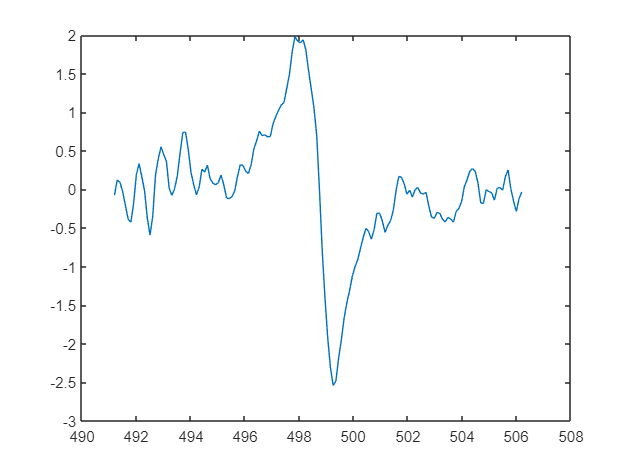

xI_ = xI(:, icw); y_ = y(:, icw);
figure()
plot(xI_ + 1.2, y_)
hold on

plot(xI_, scaleY(pepper(Sys, Exp), y_))

Error using pepper
Multiple components: Please specify sweep range manually using
Exp.Range or Exp.CenterSweep.

## Field offset for fit with two spin systems

*pepperFieldOffset *does not work with more than 1 spin system. Correction is done shifting the magnetic field array, then the shift is checked again after the fitting.

Since we noticed that one spin system fits the data well, below I fit with *peppeFieldOffset* directly and then correct the data after the fit.

xIS = xI + 1.2; % Interpolated Shifted
wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');
for icw = 1:ncw
    xIS_ = xIS(:, icw); y_ = y(:, icw);
    Exp.Range = [min(xIS_) max(xIS_)];
    Exp.mwFreq = 14;
    Fit_ = esfit(y_, @pepper, {Sys, Exp}, {Vary});
    if icw == 1
        Fit = repmat(Fit_, 1, ncw);
    else
        Fit(icw) = Fit_;
    end
    % Update B with the best value of Field Offset
    % x(:, icw) = xIS(:, icw) - Fit(icw).pfit(2);
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [150, 1]
Model function name:      pepper
Number of fit parameters: 1
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 1 active parameters...
iteration   1: value 1.01330e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.01330e-01   edge 2.70000e-02   contraction outside
iteration   3: value 1.01330e-01   edge 1.35000e-02   contraction inside
iteration   4: value 1.01330e-01   edge 6.75000e-03   contraction inside
iteration   5: value 1.01330e-01   edge 3.37500e-03   contraction inside
iteration   6: value 1.01329e-01   edge 1.68750e-03   contraction inside
iteration   7: value 1.01329e-01   edge 8.43750e-04   contraction inside
iteration   8: value 1.01329e-01   edge 4.21875e-04   contraction inside
iteration   9: value 1.01329e-01   

delete(wbar)

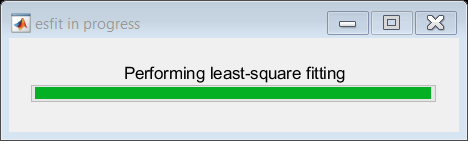

xIS = xI + 1.2; % Interpolated Shifted
x = xIS;
wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');

Sys = SysDb;
VaryDb.lw = SysDb.lw;
Vary = VaryDb;
for icw = 1:ncw
    xIS_ = xIS(:, icw); y_ = y(:, icw);
    Exp.Range = [min(xIS_) max(xIS_)];
    Exp.mwFreq = 14;
    Fit_ = esfit(y_, @pepper, {Sys, Exp}, {Vary});
    if icw == 1
        FitDb = repmat(Fit_, 1, ncw);
    else
        FitDb(icw) = Fit_;
    end
    % Update B with the best value of Field Offset
    % x(:, icw) = xIS(:, icw) - Fit(icw).pfit(2);
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [150, 1]
Model function name:      pepper
Number of fit parameters: 1
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 1 active parameters...
iteration   1: value 1.13046e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.12945e-01   edge 1.37000e-01   contraction inside
iteration   3: value 1.12834e-01   edge 6.85000e-02   contraction inside
iteration   4: value 1.12834e-01   edge 3.42500e-02   contraction inside
iteration   5: value 1.12831e-01   edge 1.71250e-02   contraction inside
iteration   6: value 1.12830e-01   edge 8.56250e-03   contraction inside
iteration   7: value 1.12830e-01   edge 4.28125e-03   contraction inside
iteration   8: value 1.12830e-01   edge 2.14063e-03   contraction inside
iteration   9: value 1.12830e-01   e

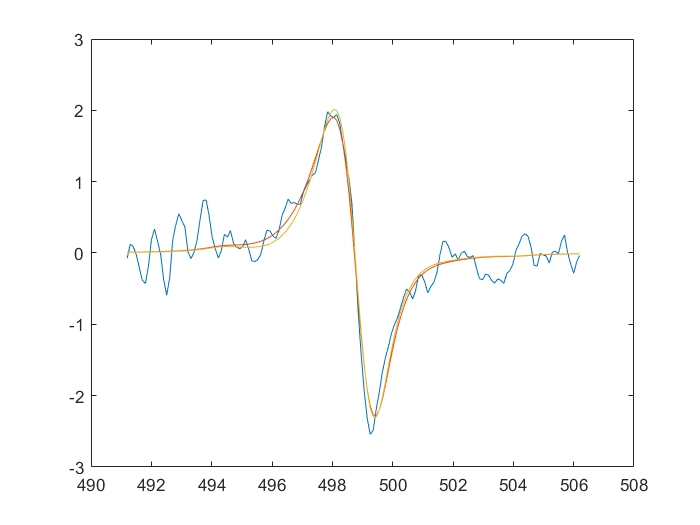

icw = 4;
figure()
plot(xIS(:, icw), y(:, icw))
hold on
plot(xIS(:, icw), Fit(icw).fit)
plot(xIS(:, icw), FitDb(icw).fit)